clear
load Apkirpta_ideali_preambule_d.mat %yy-ideali diferencijuota preambule
%Koreliacijos max priklausomybe nuo amplitudes

vienetu_generuoti = 100;

neteisingi_d = zeros(1, 19);
kiekvienas_max_d = zeros(19, vienetu_generuoti);
kiekvienas_max2_d = zeros(19, vienetu_generuoti);
kiekvienas_eng_d = zeros(19, vienetu_generuoti);

neteisingi_nd = zeros(1, 19);
kiekvienas_max_nd = zeros(19, vienetu_generuoti);
kiekvienas_max2_nd = zeros(19, vienetu_generuoti);
kiekvienas_eng_nd = zeros(19, vienetu_generuoti);

viso_viso_langas = zeros(1, 19);
viso_viso_pastumimas = zeros(1, 19);

kiekvienas_snr_db = zeros(19, vienetu_generuoti);


pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

%Nufiltruota preambule
load 'FiltroKoef.mat';
tprescaler = 10;
A = 1;
FidealPreambule = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];
FidealPreambule = [FidealPreambule, zeros(1, 70)];
filtruotaPreambule = filter(Hd, FidealPreambule);
filtruotaPreambule = filtruotaPreambule(1:10:length(filtruotaPreambule));
pastumtaFiltruotaPreambule = [zeros(1, pastumimasN), filtruotaPreambule(1:length(filtruotaPreambule)-pastumimasN)];
diferencijuotaFiltruotaPreambule = filtruotaPreambule - pastumtaFiltruotaPreambule;
diferencijuotaFiltruotaPreambule = 1.5*diferencijuotaFiltruotaPreambule;

dataSend = "101101";

%Ref itampa 1.4V
%for langas = 70:10:100
langas = 50;
for pastumimasN = pastumimasN%1:1:10
    neteisingi = 0;
    pastumimas_temp = [];

    temp_preambules_max1_error_max = zeros(1, vienetu_generuoti);
    temp_preambules_max1_error_min = zeros(1, vienetu_generuoti);
    temp_preambules_max2_error_max = zeros(1, vienetu_generuoti);
    temp_preambules_max2_error_min = zeros(1, vienetu_generuoti);
    
    generuojama_amplitude_viso = 0.2:0.05:1.1;
    for generuojama_amplitude_index = 1:19
        generuojama_amplitude = generuojama_amplitude_viso(generuojama_amplitude_index);
        
        vienetai_d = 0;
        vienetai_nd = 0;
        
        nepataikyta_d = 0;
        nepataikyta_nd = 0;
        
        for i = 1:vienetu_generuoti
            [idealSignal, noisySignal, discretizedSignal, ADCsignal2, ADCpreambule, signalSNR_db] = GenerateSignal(dataSend, generuojama_amplitude);
            kiekvienas_snr_db(generuojama_amplitude_index, i) = signalSNR_db;
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
            
            ma_ilgis = 5;
            ADCsignal2_ma = GenerateMA(ADCsignal2, ma_ilgis);
            pastumtas_ma = [zeros(1, pastumimasN), ADCsignal2_ma(1:length(ADCsignal2_ma)-pastumimasN)];
            diferencijuotasPilnas_ma = ADCsignal2_ma - pastumtas_ma; %GenerateMA(diferencijuotasPilnas, ma_ilgis);
            diferencijuotaPreambule_ma = GenerateMA(diferencijuotaPreambule, ma_ilgis);
            idealPreambule_ma = GenerateMA(idealPreambule, ma_ilgis);
           
            %y = GenerateConv(y, yy); %diferencijuotas DVIGUBAI
            %y_d = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
            %y_nd = GenerateConv(ADCsignal2, idealPreambule); %Nediferencijuoptas
            
            %y_d = GenerateConv(diferencijuotasPilnas_ma, diferencijuotaPreambule_ma); %Diferencijuotas
            %y_d = GenerateConv(diferencijuotasPilnas_ma, diferencijuotaPreambule); %Diferencijuotas
            %y_nd = GenerateConv(ADCsignal2_ma, idealPreambule_ma); %Nediferencijuoptas
            %y_nd = GenerateConv(ADCsignal2_ma, idealPreambule); %Nediferencijuoptas
            
            %Filtruotos preambules
            y_d = GenerateConv(diferencijuotasPilnas, diferencijuotaFiltruotaPreambule); %diferencijuota filtruota
            y_nd = GenerateConv(ADCsignal2, filtruotaPreambule); %Nediferencijuopta filtruota
            
            %TIkrinam diferencijuota
            [maksimumai, indeksai] = findpeaks(y_d(1:320), 'SortStr','descend', 'MinPeakDistance',5);
            %[maksimumai, indeksai] = maxk(y_d(1:330),2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            %if index_y > 310 && index_y < 316 %paprastas
            if index_y > 304 && index_y < 320 %filtruotas
                vienetai_d = vienetai_d + 1;

                kiekvienas_eng_d(generuojama_amplitude_index, i) = sum(abs(ADCsignal2(index_y-langas:index_y) .* ADCsignal2(index_y-langas:index_y)))/langas;
                kiekvienas_max_d(generuojama_amplitude_index, i) = max_y;
                kiekvienas_max2_d(generuojama_amplitude_index, i)= max_y2;
            else
                nepataikyta_d = nepataikyta_d + 1;
            end

            %TIkrinam NEdiferencijuota
            [maksimumai, indeksai] = findpeaks(y_nd(1:320), 'SortStr','descend', 'MinPeakDistance',5);
            %[maksimumai, indeksai] = maxk(y_nd(1:330),2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            %if index_y > 310 && index_y < 316 %%paprastas
            if index_y > 304 && index_y < 310 %filtruotas
                vienetai_nd = vienetai_nd + 1;

                kiekvienas_eng_nd(generuojama_amplitude_index, i) = sum(abs(ADCsignal2(index_y-langas:index_y) .* ADCsignal2(index_y-langas:index_y)))/langas;
                kiekvienas_max_nd(generuojama_amplitude_index, i)= max_y;
                kiekvienas_max2_nd(generuojama_amplitude_index, i)= max_y2;
            else
                nepataikyta_nd = nepataikyta_nd + 1;
            end
            
        end

        neteisingi_d(generuojama_amplitude_index) = nepataikyta_d;
        neteisingi_nd (generuojama_amplitude_index) = nepataikyta_nd;
       
        %{
        [a, ~] = max(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        [a, ~] = min(sugeneruoti_max);
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
    
        [a, ~] = max(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        [a, ~] = min(sugeneruoti_max2);
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}
    end
    %preambules_max1_error_max = [preambules_max1_error_max; temp_preambules_max1_error_max];
    %preambules_max1_error_min = [preambules_max1_error_min; temp_preambules_max1_error_min];
    %preambules_max2_error_max = [preambules_max2_error_max; temp_preambules_max2_error_max];
    %preambules_max2_error_min = [preambules_max2_error_min; temp_preambules_max2_error_min];
    
    %viso_neteisingi_d = [viso_neteisingi_d; neteisingi_d];
    %viso_neteisingi_nd = [viso_neteisingi_nd; neteisingi_nd];
end

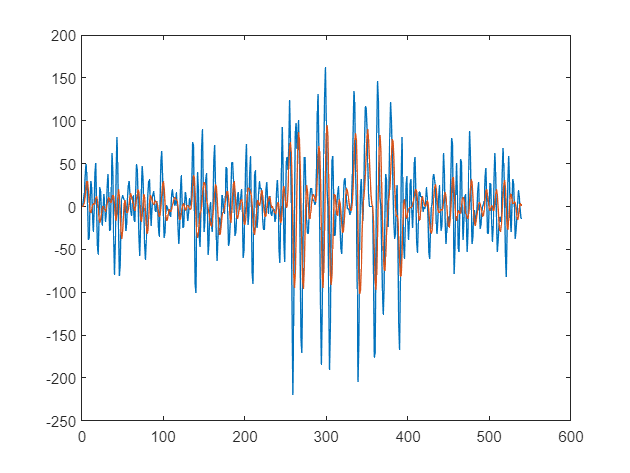

figure
plot(diferencijuotasPilnas)
hold on
plot(diferencijuotasPilnas_ma)
hold off

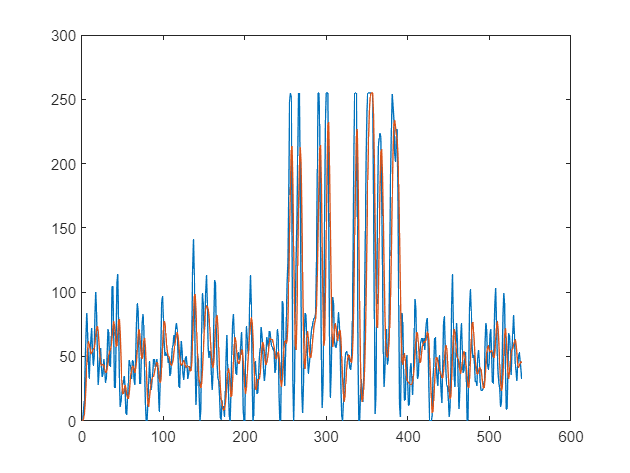


plot(ADCsignal2)
hold on
plot(ADCsignal2_ma)
hold off

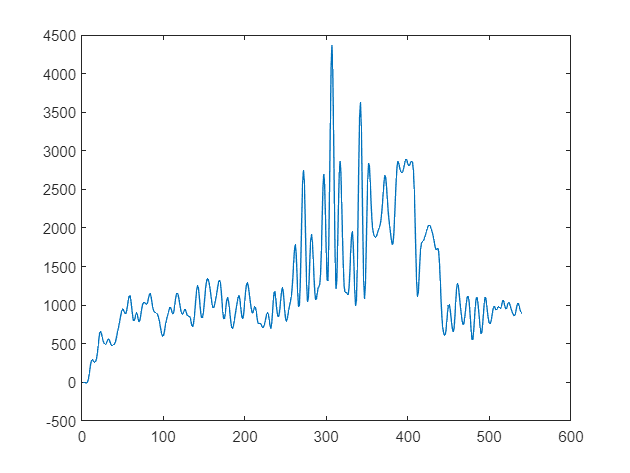


plot(y_nd)
%[aukstis, vieta] = findpeaks(y_nd(1:330), 'SortStr','descend', 'MinPeakDistance',5);
hold on
%scatter(vieta, aukstis)
hold off

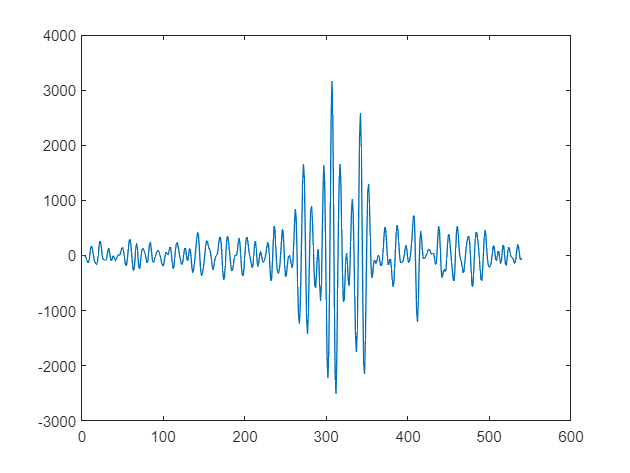


plot(y_d)

viso_max_duom_d = mean(kiekvienas_max_d, 2)';
viso_max_duom_nd = mean(kiekvienas_max_nd, 2)';

viso_max_duom2_d = mean(kiekvienas_max2_d, 2)';
viso_max_duom2_nd = mean(kiekvienas_max2_nd, 2)';

viso_eng_duom_d =  mean(kiekvienas_eng_d, 2)';
viso_eng_duom_nd =  mean(kiekvienas_eng_nd, 2)';



%norm_preambules_max1_error_min = abs(viso_max_duom - preambules_max1_error_min);
%norm_preambules_max1_error_max = abs(preambules_max1_error_max - viso_max_duom);
%norm_preambules_max2_error_min = abs(viso_max_duom2 - preambules_max2_error_min);
%norm_preambules_max2_error_max = abs(preambules_max2_error_max - viso_max_duom2);

%skirtumasLowHigh = (preambules_max1_error_min - preambules_max2_error_max) ./ viso_max_duom;

%kiekvienas_skirtumas = kiekvienas_max - kiekvienas_max2;
%kiekvienas_mean = mean(kiekvienas_skirtumas);
%kiekvienas_mean_skirtumas = kiekvienas_skirtumas - kiekvienas_mean;

%kiekvienas_max_deviacija = mean(kiekvienas_max) - kiekvienas_max;

minKvantiliai_d = [];
maxKvantiliai_d = [];
minKvantiliai_nd = [];
maxKvantiliai_nd = [];
for i = 1:19
    minKvantiliai_d = [minKvantiliai_d, nonzeros(quantile(kiekvienas_max_d(i, :), 0.25))];
    maxKvantiliai_d = [maxKvantiliai_d, nonzeros(quantile(kiekvienas_max_d(i, :), 0.75))];
    minKvantiliai_nd = [minKvantiliai_nd, nonzeros(quantile(kiekvienas_max_nd(i, :), 0.25))];
    maxKvantiliai_nd = [maxKvantiliai_nd, nonzeros(quantile(kiekvienas_max_nd(i, :), 0.75))];
end
max_vidurkis_d = mean(kiekvienas_max_d, 2)';
max_vidurkis_nd = mean(kiekvienas_max_nd, 2)';

%errMin_d = minKvantiliai_d - max_vidurkis_d;
errMax_d = maxKvantiliai_d - max_vidurkis_d;

%errMin_nd = minKvantiliai_nd - max_vidurkis_nd;
errMax_nd = maxKvantiliai_nd - max_vidurkis_nd;

figure
%errorbar(1:1:19, max_vidurkis_d, errMin_d, errMax_d)
hold on
%errorbar(1:1:19, max_vidurkis_nd, errMin_nd, errMax_nd)

legend("Max diferencijuotas", "Max nediferencijuotas")

hold off
%plot(abs(errMin_d./errMax_d))
hold on
%plot(abs(errMin_nd./errMax_nd))
title("Santykis tarp skirtumu peako pirmo")
legend("Diferencijuotas", "Nediferencijuotas")

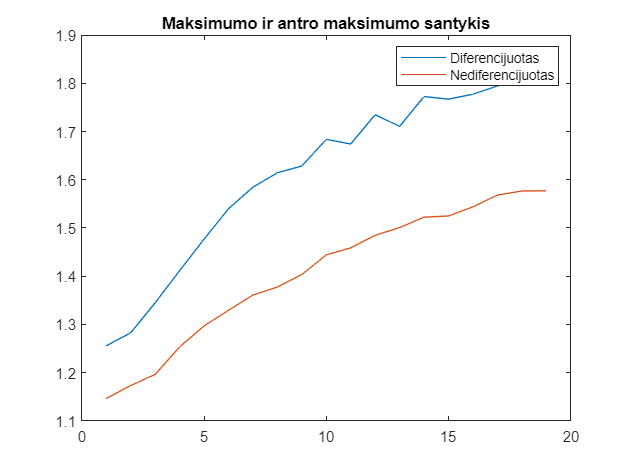

hold off
viso_santykis_d = viso_max_duom_d./viso_max_duom2_d;
viso_santykis_nd = viso_max_duom_nd./viso_max_duom2_nd;

plot(viso_santykis_d)
hold on
plot(viso_santykis_nd)
hold off
title("Maksimumo ir antro maksimumo santykis")
legend("Diferencijuotas", "Nediferencijuotas")

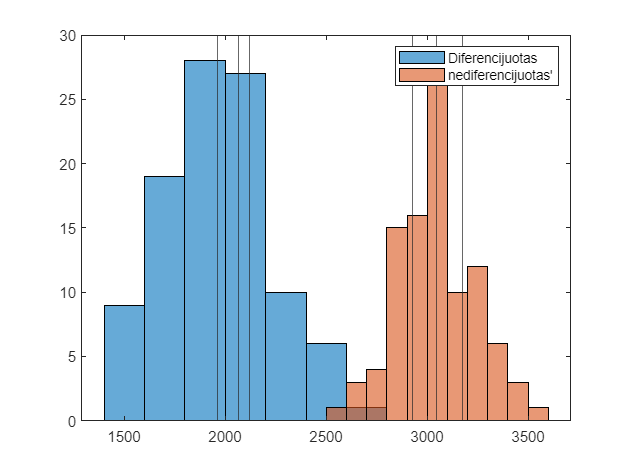


rodomasIndex = 10;

histogramai_d = nonzeros(kiekvienas_max_d(rodomasIndex, :))';
histogramai_nd = nonzeros(kiekvienas_max_nd(rodomasIndex, :))';

histograma_d = histogram(histogramai_d);
hold on
histograma_nd = histogram(histogramai_nd);

xline(minKvantiliai_d(rodomasIndex))
xline(maxKvantiliai_d(rodomasIndex))
xline(mean(kiekvienas_max_d(rodomasIndex, :)))

xline(minKvantiliai_nd(rodomasIndex))
xline(maxKvantiliai_nd(rodomasIndex))
xline(mean(kiekvienas_max_nd(rodomasIndex, :)))

legend("Diferencijuotas", "nediferencijuotas'")
hold off

mean(nonzeros(kiekvienas_max_d(rodomasIndex, :)))

ans = 1.9593e+03

std(nonzeros(kiekvienas_max_d(rodomasIndex, :)))

ans = 257.7578

std(nonzeros(kiekvienas_max_nd(rodomasIndex, :)))

ans = 191.8948

rodomasIndex = 1;
rangeas = 3:19;

%p = polyfit([0, viso_viso_eng(rodomasIndex, :)], [0, viso_max_duom(rodomasIndex, :)], 2);
%p = polyfit(viso_viso_eng(rodomasIndex, rangeas), viso_max_duom(rodomasIndex, rangeas)-norm_preambules_max1_error_min(rodomasIndex, rangeas), 2);
%p = polyfit([0, viso_eng_duom_d(1, :)], [1800, viso_max_duom_d(1, :)], 2);
p = polyfit(viso_eng_duom_nd(1, rangeas), viso_max_duom_nd(1, rangeas), 2);
%p = polyfit([0, viso_viso_eng(rodomasIndex, rangeas)], [1000, maxKvantiliai(rodomasIndex, rangeas)], 2);
p

p =    -0.0000    0.2878  524.2078


p_fit_x = 0:1000:25000;
p_fit = polyval(p, p_fit_x);
p_fitt = 2000^2*p(1)+2000*p(2)+p(3)%-1285.4 + 3000*1.0267

p_fitt = 1.0808e+03

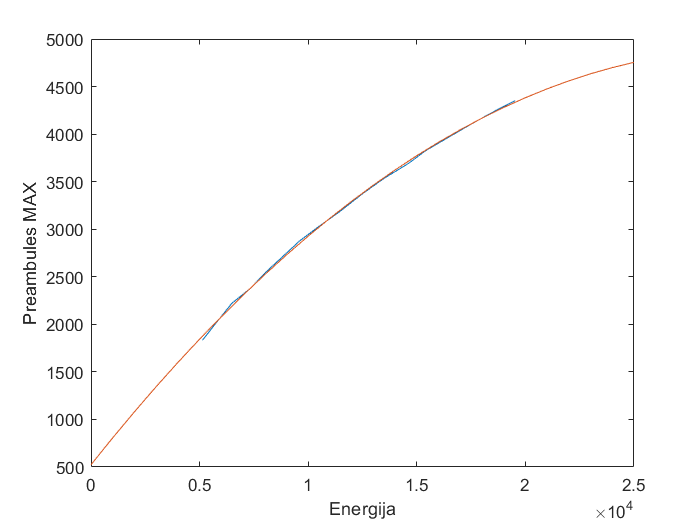

figure
plot(viso_eng_duom_nd(rodomasIndex, rangeas), viso_max_duom_nd(rodomasIndex, rangeas))
xlabel("Energija")
ylabel("Preambules MAX")
hold on
plot(p_fit_x, p_fit)
hold off

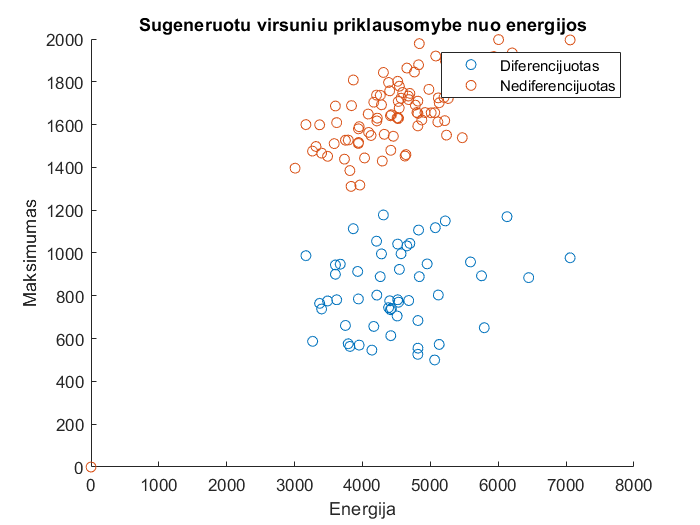

figure
scatter(kiekvienas_eng_d(1, :), kiekvienas_max_d(1, :))
hold on
scatter(kiekvienas_eng_nd(1, :), kiekvienas_max_nd(1, :))
hold off
ylabel("Maksimumas")
xlabel("Energija")
title("Sugeneruotu virsuniu priklausomybe nuo energijos")
legend("Diferencijuotas", "Nediferencijuotas")

%Diferencijuotas
R_d = corr2(kiekvienas_eng_d(8, :), kiekvienas_max_d(8, :))

R_d = 0.1873

%Nediferencijuotas
R_nd = corr2(kiekvienas_eng_nd(8, :), kiekvienas_max_nd(8, :))

R_nd = 0.8574

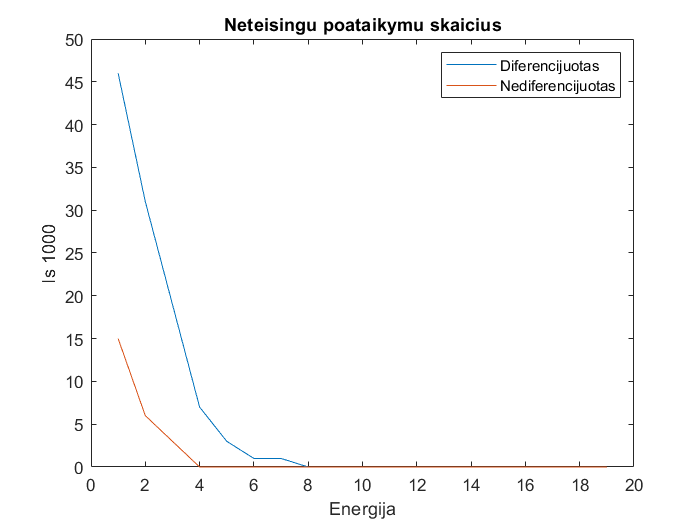

figure
plot(neteisingi_d)
hold on
plot(neteisingi_nd)
legend("Diferencijuotas", "Nediferencijuotas")
title("Neteisingu poataikymu skaicius")
xlabel("Energija")
ylabel("Is 1000")
hold off


%Pavirsius nuo pastumimo, rms ir skirtumo tarp peaku, turi sugeneruoti
%pastumima visa
%surf(rms_duom, pastumimas_duom, viso_skirtumas)
%surf(rms_duom, langas_duom , viso_skirtumas)
%surf(eng_duom, langas_duom , viso_skirtumas)
%xlabel("RMS");
%ylabel("Pastumimas");
%zlabel("Skirtumas");
%figure
%scatter3(viso_viso_rms(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%scatter3(viso_viso_eng(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%scatter3(viso_viso_pastumimas(:), viso_viso_rms(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%xlabel("X RMS")
%ylabel("Y Lango ilgis")
%zlabel("Z Skirtumas")